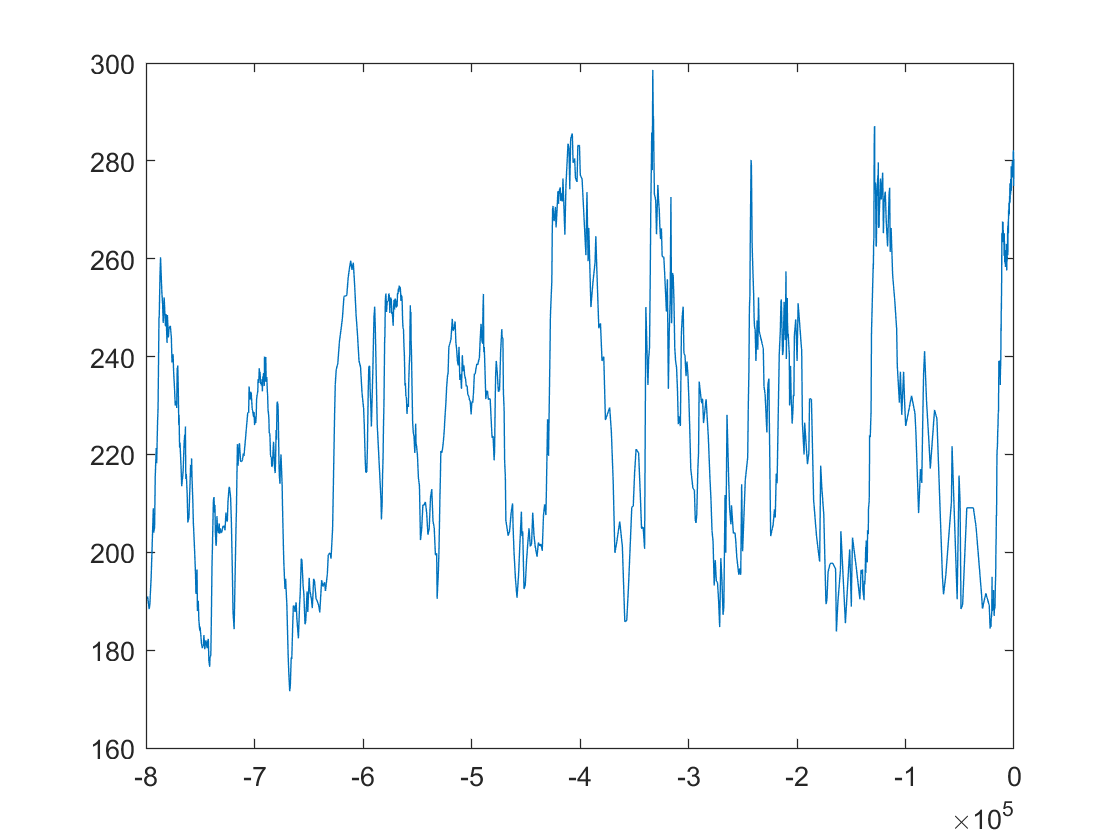

close all;
clc;
warning("off","all")

% make data object
[obj_arr, mset_arr] = make_objs();
obj_co2 = obj_arr{1};
plot(obj_co2.X,obj_co2.Y);

% set number of "years" and "months" to divide data into
Y = 20;
M = 100;

% run findanf, plot results
close all;
hold on;
darr = [2,5,10,15,17];
for d=darr
    [a_final,~,f,P_final] = findanf_epica(obj_co2,Y,M,d,1);
    plot(a_final);
end

[a_est,N] = findanf_woosok(obj_co2,Y,M);
disp(mean(a_est));

  -1.3217e-05



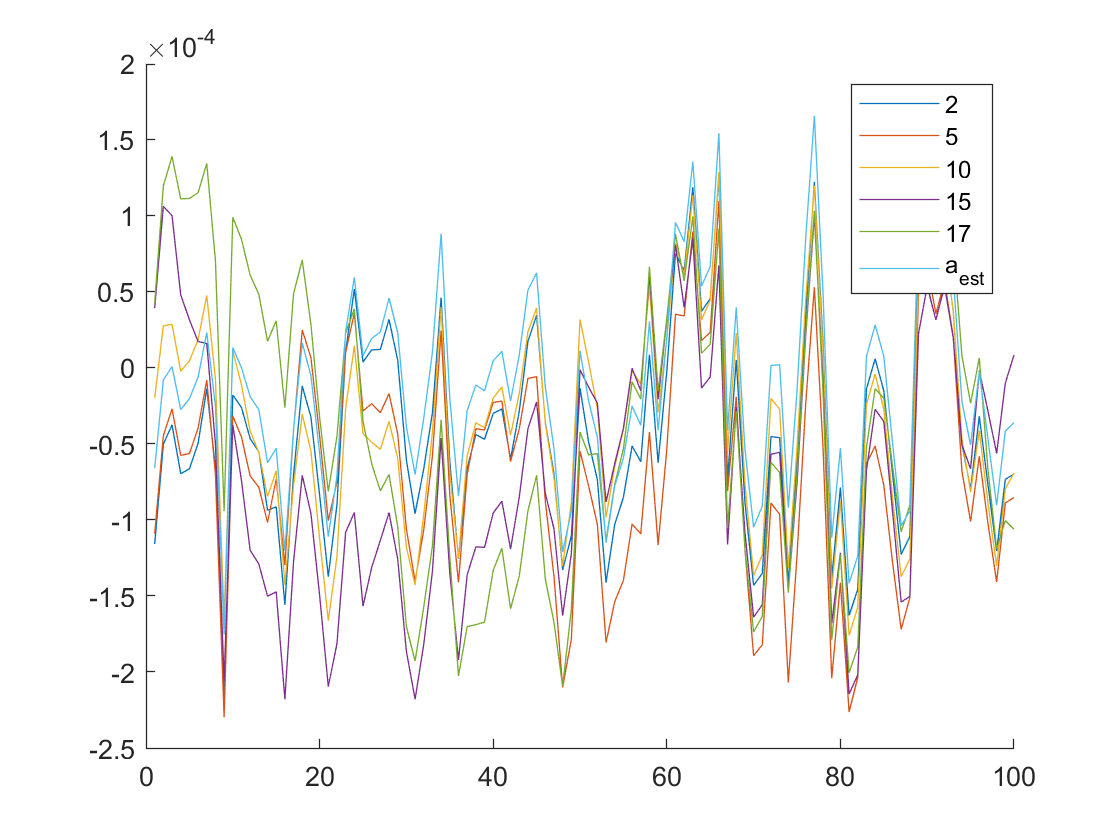

plot(a_est);

legend("2","5","10","15","17","a_{est}");

M_length = range(obj_co2.X) / (Y*M)

M_length = 798.3750


mean(a_est)

ans = -1.9267e-05

int_aest = sum(a_est) / M_length

int_aest = -1.2066e-06

T_aest = 1 / abs(int_aest)

T_aest = 8.2877e+05

num_M_est = T_aest / M_length

num_M_est = 1.0381e+03

num_Y_est = num_M_est / M

num_Y_est = 20.7614

mean(a_final)

ans = -7.0435e-05

int_a = sum(a_final) / M_length

int_a = -4.4112e-06

T_a = 1 / abs(int_a)

T_a = 2.2670e+05

num_M = T_a / M_length

num_M = 283.9486

num_Y = num_M / M

num_Y = 5.6790